clear variables

Signal émis

A=1;
Fs=1000;
f0=7;
T0=1/f0;
T=5*T0;
D=3*T;
t=[0:1/Fs:D];

p = abs((t-T/2)/T)<1/2;

x = A.*cos(2*pi*f0*t).*p;


Signal reçu

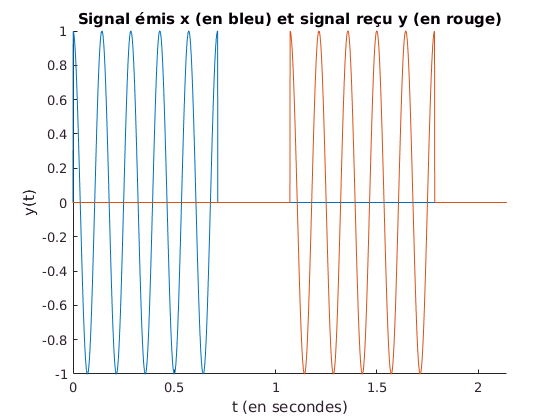

tau0=1.5*T;
p2 = abs((t-tau0-T/2)/T)<1/2;
y = A.*cos(2*pi*f0*(t-tau0)).*p2;

figure(1)
hold on
plot(t,x)
plot(t,y)
title('Signal émis x (en bleu) et signal reçu y (en rouge)')
xlabel('t (en secondes)')
ylabel('y(t)')
xlim([0 D])

Fonction d'inter-corrélation

Il faut normaliser par 1/Fs pour avoir une intégrale et non pas des rectangles

k représente le retard entre les signaux y(t) et x(t)

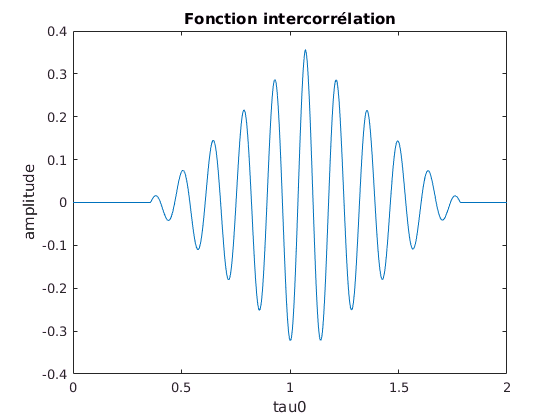

[r,lags] = xcorr(y,x);
r=(1/Fs)*r;
lags=(1/Fs)*lags;

figure(2)
plot(lags,r)
title('Fonction intercorrélation')
xlabel('tau0')
ylabel('amplitude')
axis([0 2 -0.4 0.4])

Fréquence des oscillations : En mesurant avec les curseurs, on obtient une fréquence de 7Hz. On retrouve bien la fréquence f0.

On a une pente décroissante de -0.5 qui correspond à la pente décroissante de la fonction théorique. 

Le support de la fonction est compacte car la fonction d'intercorrélation a une fonction triangle en facteur, fonction qui est elle-même compacte.

Max de intercorr(y,x) : 0.3568

La valeur maximale de la fonction d'intercorrélation de (y,x) correspond à l'énergie du signal x car intercorr(y,x) à tau=0 vaut A^2*T/2

[m,i]=max(r);
to0=lags(i);

to0 est le temps de propagation.

Signal avec un média bruité

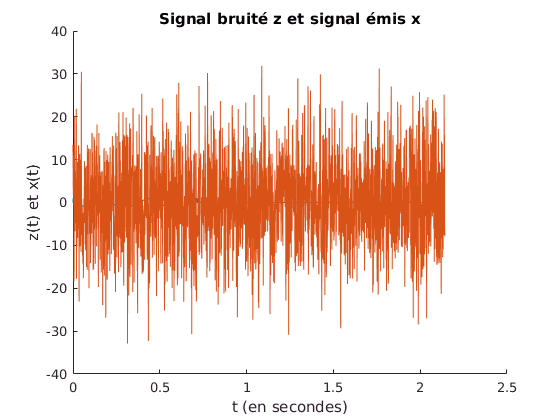

sigma=10;
z = y+sigma*randn(size(y));

figure(3)
hold on
plot(t, x)
plot(t, z)
title('Signal bruité z et signal émis x')
xlabel('t (en secondes)')
ylabel('z(t) et x(t)')

 Fonction d'inter-corrélation entre z et x

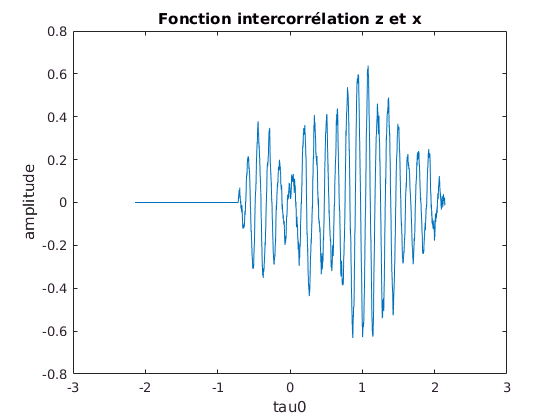

[r2,lags2] = xcorr(z,x);
r2=(1/Fs)*r2;
lags2=(1/Fs)*lags2;

figure(4)
plot(lags2,r2)
title('Fonction intercorrélation z et x')
xlabel('tau0')
ylabel('amplitude')

inter-corr entre z et x = inter-corr entre y+b et x (car z = y+b avec y le signal reçu sans bruit et b le bruit) = inter-corr entre y et x + inter-corr entre b et x

C'est pour cela que l'on retrouve une fonction d'inter-corrélation entre z et x qui ressemble à celle entre y et b mais elle est différente car on ajoute une fonction d'inter-corrélation entre b et x

[m2,i2]=max(r2);
to0

to0 = 1.0710

to1=lags2(i2)

to1 = 1.0800


erreur=abs(to0-to1)/to0*100

erreur = 0.8403

Le temps de propagation avec le bruit est très différent de celui sans bruit.

Echo

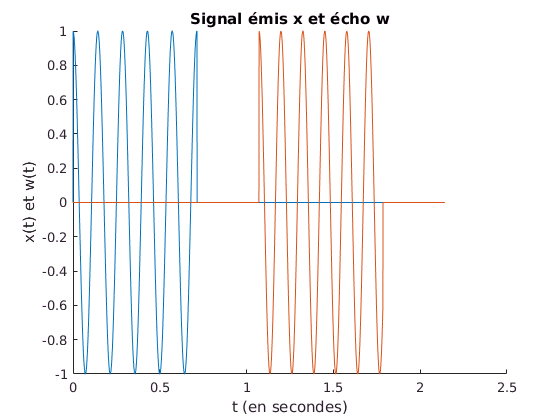

deltaF=0.13*f0;
p3 = abs((t-tau0-T/2)/T)<1/2;
w = cos(2*pi*(f0+deltaF)*(t-tau0)).*p3;

figure(5)
hold on
plot(t,x)
plot(t,w)
title('Signal émis x et écho w')
xlabel('t (en secondes)')
ylabel('x(t) et w(t)')

Fonction d'inter-corrélation entre w et x

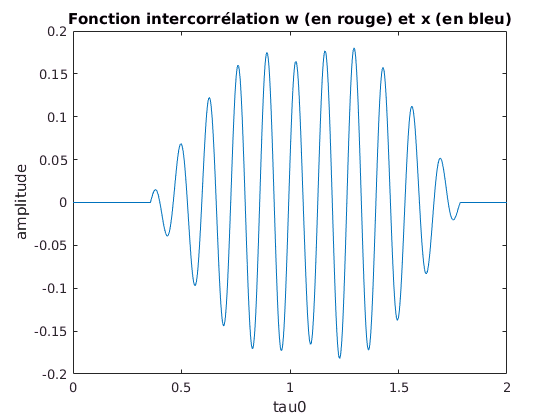

[r3,lags3] = xcorr(w,x);
r3=(1/Fs)*r3;
lags3=(1/Fs)*lags3;

figure(6)
plot(lags3,r3)
title('Fonction intercorrélation w (en rouge) et x (en bleu)')
xlabel('tau0')
ylabel('amplitude')
axis([0 2 -0.2 0.2])


[m3,i3]=max(r3);
to3=lags3(i3);

erreur=abs(to0-to3)/to0*100;

Le temps de propagation estimé à partir de la fonction d'inter-corrélation entre w et x est très différente de celle théorique, en effet, on trouve une erreur de 21%

Avec 4 périodes de T0, on obtient une valeur satisfaisante pour le temps de propagation obtenue (erreur de 4% avec celui théorique). On a choisi 4 périodes et non pas moins de périodes afin d'essayer de rendre le bruit le plus négligeable possible tout en ayant une valeur de temps de propagation acceptable par rapport à celle théorique. En effet, en augmentant le nombre de périodes de T0, on diminue l'influence du bruit jusqu'à le rendre négligeable alors qu'en diminuant le nombre de périodes, on a un temps de propagation plus acceptable. On fait un compromis.

Densité inter-spectrale d'énergie entre w et x

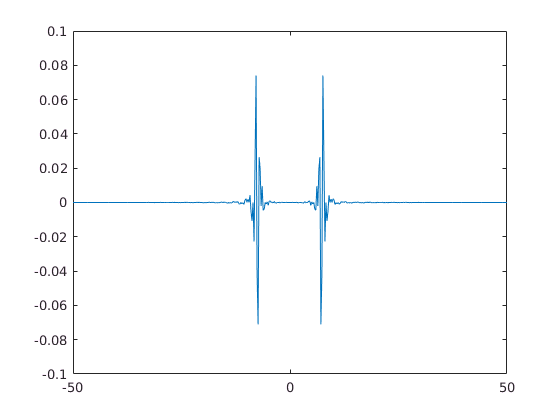

[S,f] = TransFourier(r3,lags3);

figure(7)
plot(f, real(S))
axis([-50 50 -0.1 0.1])